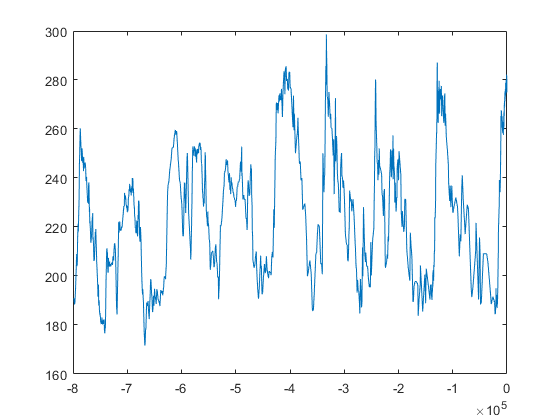

close all;
clc;
warning("off","all")

% make data object
[obj_arr, mset_arr] = make_objs();
obj_co2 = obj_arr{1};
plot(obj_co2.X,obj_co2.Y);

% set number of "years" and "months" to divide data into
Y = 20;
M = 200;
d = 18;

% run findanf, plot results
[a_final,~,f,P_final] = findanf_epica(obj_co2,Y,M,d,1);

finding B with d=18 :


disp(mean(a_final));

  -4.4695e-05



disp(a_final(end-10:end));

   1.0e-03 *

    0.0284
    0.0938
    0.1424
    0.1355
    0.1250
    0.0792
    0.0827
    0.1947
    0.1858
    0.1883
   -0.7143




close all;
hold on;
plot(a_final);

[a_est,N,d] = findanf_woosok(obj_co2,Y,M);
disp(mean(a_est));

  -1.2006e-05



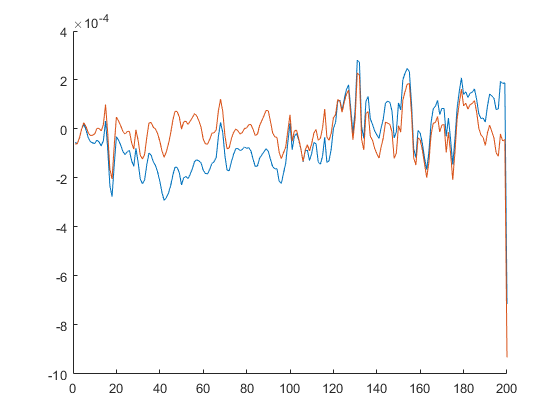

plot(a_est);

M_length = range(obj_co2.X) / (Y*M)

M_length = 798.3750


sum(a_est)

ans = -0.0012

int_aest = sum(a_est) / M_length

int_aest = -1.4967e-06

T_aest = 1 / abs(int_aest)

T_aest = 6.6814e+05

num_M_est = T_aest / M_length

num_M_est = 836.8761

num_Y_est = num_M_est / M

num_Y_est = 16.7375

sum(a_final)

ans = -0.0067

int_a = sum(a_final) / M_length

int_a = -8.4056e-06

T_a = 1 / abs(int_a)

T_a = 1.1897e+05

num_M = T_a / M_length

num_M = 149.0129

num_Y = num_M / M

num_Y = 2.9803